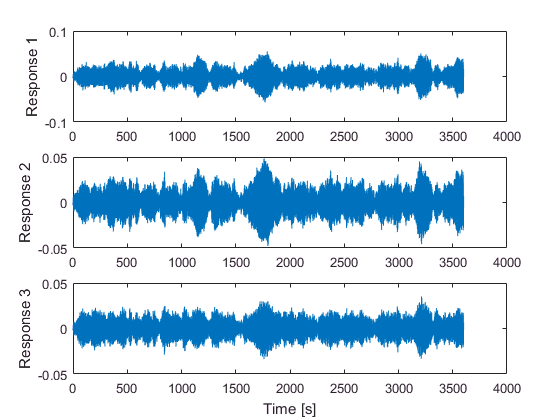

import ../../koma.*
close all
clear all

% Demo script for Cov-SSI. Kvåle, 2017.
imported = load('example_data.mat');
data_clean = imported.u;
levels = imported.levels;
fs = imported.fs;
f = imported.f;
S = imported.S;
lambda_ref = imported.lambda_ref;

t = 0:1/fs:(1/fs)*(size(data_clean, 1)-1);

%% Plot results
for i = 1:levels
    subplot(levels,1,i)
    plot(t, data_clean(:,i))
    ylabel(['Response ', num2str(i)])
end
xlabel('Time [s]')

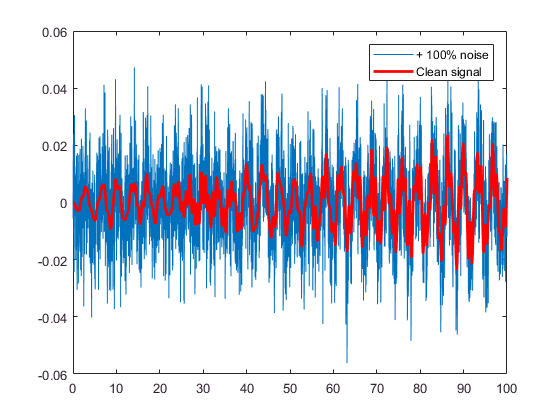


%% Noise plot, mid-level
figure(100),clf
noise = 1*mean(std(data_clean));
data = data_clean + noise*randn(size(data_clean));

plot(t, data(:,2))
hold on
plot(t, data_clean(:,2),'red','linewidth',2)
xlim([0,100])
legend({'+ 100% noise' 'Clean signal'})

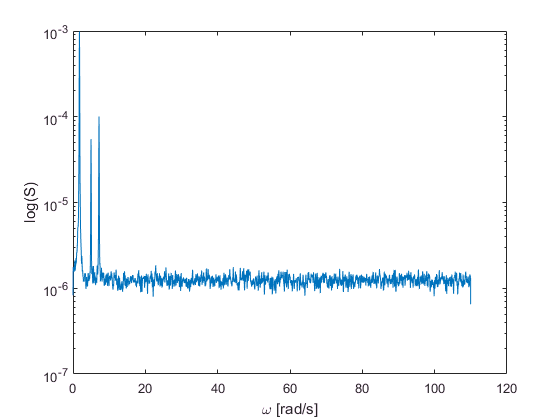


%% Geometry data for mode interpretation
path='geometry\';
slave=dlmread([path 'slave.asc']);
elements=dlmread([path 'elements.asc']);
griddef=dlmread([path 'grid.asc']);
active_nodes=[4,6,8];   %corresponding to nodes in grid-matrix; the nodes that are represented in the mode shape vector

%% Plot spectral density
figure(3), clf

semilogy(f*2*pi,S(:,2)/2/pi)
ylabel('log(S)')
xlabel('\omega [rad/s]')
hold on

%% SSI run
i = 20;    %blockrows
order = 2:2:50;

figure(5)
fs_rs = ceil(2*max(abs(lambda_ref)/2/pi));
data_rs = resample(detrend(data),fs_rs,fs);

% Extend data matrix to 3d (for easy plotting of mode shapes, not necessary for ssi)
data_3d = zeros(size(data_rs,1),3*size(data_rs,2));
data_3d(:,1:3:end) = data_rs;
data_3d(:,2:3:end) = 0*data_rs;
data_3d(:,2:3:end) = 0*data_rs;

[lambda,phi,order] = koma.oma.covssi(data_3d, fs_rs, i, 'order',order);

*** COVARIANCE DRIVEN SSI ALGORITHM FOR OPERATIONAL MODAL ANALYSIS ****
* ESTABLISHING HANKEL AND TOEPLITZ MATRICES
  ** Correlation estimation
  ** Matrix stacking
* CALCULATING SVD OF MATRICES AND CONTROLLING MAXIMUM ORDER
  ** Rank(D) = 60
  ** Maximum system order used is n_max = 50
* ESTABLISHING WEIGHTING MATRIX
* COMPUTING STATE MATRIX FROM DECOMPOSITION FOR EACH ORDER, AND ESTABLISH EIGENVALUES AND EIGENVECTORS
* COMPUTATION COMPLETE!


ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


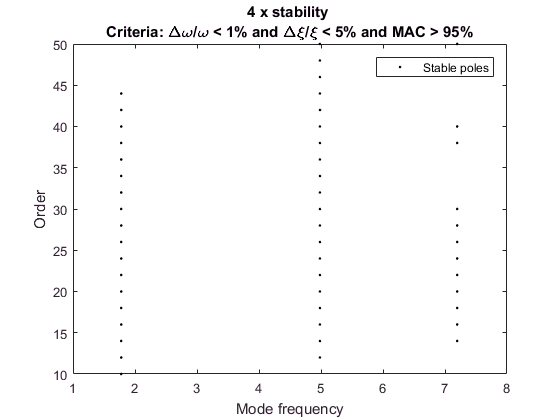

koma.vis.stabplot(lambda,phi,order,'plot','stable','indicator','freq','stablevel',4,'selection',true,'grid',griddef,'slave',slave,'elements',elements,'active_nodes',active_nodes)